# Air density

clear;
close all;

par = get_car_param();

R = 8.1345; %J/mol/K
Mair = 28.96e-3; %kg/mol
p0 = 101325; %Pa
T = [0:10:50] + 273.15; %K
g = 9.81; %m/s^2

h = linspace(0, 1000, 100);

Function

density = @(h,T) p0*Mair ./ (R*T) .* exp(-Mair*g*h ./ (R*T));

#### Plot

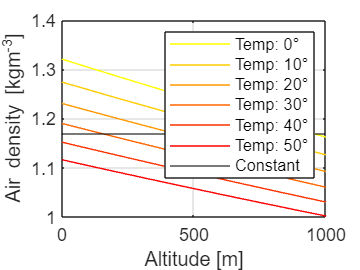

len_T = length(T);
colormap = autumn(len_T);

figure
hold on
for i = 1:len_T
    name = ['Temp: ', char(num2str(T(i)-273.15)), '°'];
    plot(h, density(h,T(i)), 'r', 'Color', colormap(end+1-i,:), 'DisplayName', name)
end
yline(par.rho_a, 'k', 'DisplayName', 'Constant')
xlabel("Altitude [m]")
ylabel("Air density [kgm^{-3}]")
legend()
box on
grid on